# Matrices de Transformación Homogénea

Estas matrices tienen tmaño 4x4 y relacion la posición y orientación entre sistemas de referencia.

En una sola matriz se combinan un matriz de rotación y un vector de desplazamiento.

Para este ejemplo se define una matriz de transformación que ralciona un sistema '1' con respecto a un sistema '0', observe la matriz de rotación en la submatriz superior izquierda y el vectr de desplazamiento en la última columna. El uno en la úlmia fila y columna es la coordenada homegénea.

T1_0 = [0.685790 -0.529446 0.499377 1.5;
    0.530497 -0.106103 -0.841019 -2;
    0.498261 0.841681 0.208105 1.2;
    0 0 0 1];

Se obtienen los vectores unitarios de los ejes del sistema 1 con respecto al sistema 0. En punteado está el sistema 0 y en linea continua el sistema 1 visto desde el sistema 0.

axes_1 = T1_0 * [1 0 0 0;
               0 1 0 0;
               0 0 1 0;
               0 0 0 1];

figure(1)
title('Transformación Homogénea')
xlabel('X')
ylabel('Y')
zlabel('Z')
hold on
%Ejes fijos
plot3([0 1],[0 0],[0 0],'--r','LineWidth',0.5)
plot3([0 0],[0 1],[0 0],'--g','LineWidth',0.5)
plot3([0 0],[0 0],[0 1],'--b','LineWidth',0.5)

plot3([axes_1(1,4) axes_1(1,4)+axes_1(1,1)], ...
      [axes_1(2,4) axes_1(2,4)+axes_1(2,1)], ...
      [axes_1(3,4) axes_1(3,4)+axes_1(3,1)], ...
      '-r','LineWidth',1)

plot3([axes_1(1,4) axes_1(1,4)+axes_1(1,2)], ...
      [axes_1(2,4) axes_1(2,4)+axes_1(2,2)], ...
      [axes_1(3,4) axes_1(3,4)+axes_1(3,2)], ...
      '-g','LineWidth',1)

plot3([axes_1(1,4) axes_1(1,4)+axes_1(1,3)], ...
      [axes_1(2,4) axes_1(2,4)+axes_1(2,3)], ...
      [axes_1(3,4) axes_1(3,4)+axes_1(3,3)], ...
      '-b','LineWidth',1)



Ahora se har'la suposición que hay un punto cuyas coordenadas en el sistema de referencia 1 son [0.5 0.5 0.5]'. ¿Cuales serán las coordenadas de ese mismo punto pero desde el sistema 0?

Para resolver esa pregunta simplemente es necesario multiplicar el vector homogéneo del punto por la matriz de transformación homogénea

P_1 = [0.5; 0.5; 0.5; 1];

P_0 = T1_0 * P_1

P_0 =     1.8279
   -2.2083
    1.9740
    1.0000


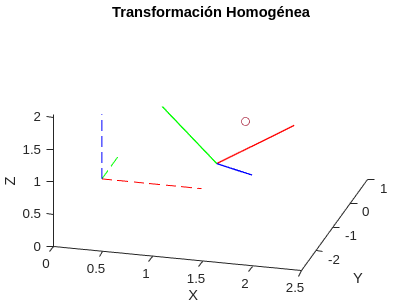


scatter3(P_0(1), P_0(2), P_0(3))
hold off